# How to Properly Scale Fourier Transformed Signals.

Suppose we measured a signal and took its Fourier Transform. Displaying the result, we would want to make sense of the output. For example, if there are resonant peaks, we would want to know the frequency at which those peaks occur.  In this notebook, we discuss how to get the proper scaling of the frequency axis.

Let's first make a test signal. 

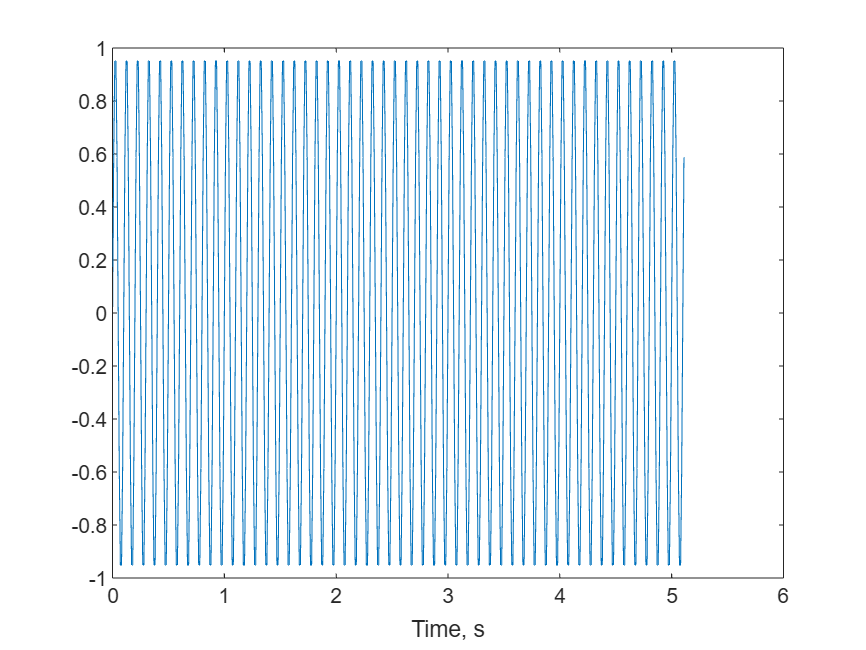

dt = 0.01; %sampling interval
N = 512; %number of samples
T = (N-1)*dt; %sampling window length
t = [0:dt:T];
fo = 10; %frequency of sinusoid

y = sin(2*pi*fo*t);
plot(t,y); xlabel('Time, s')

Now let's take the FT of y and display the modulus. Always remember that the FT result is complex. We also divide the FT by the total number of samples N to scale the amplitude axis properly.

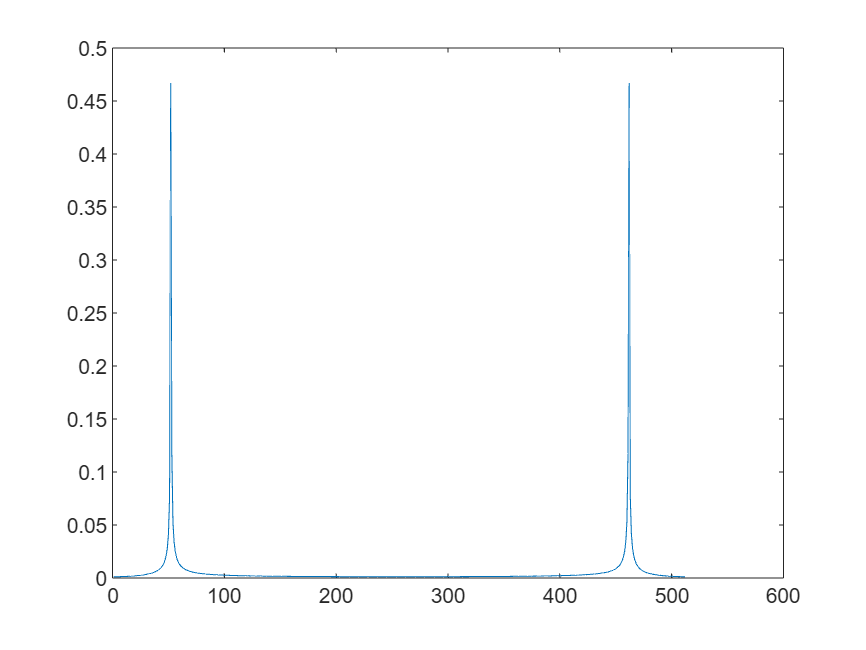

FY = fft(y);
plot(abs(FY)/N); 

Without converting the x-axis into frequency units, we do not know the value of the frequency where the peak occurs. The numbers that you see in the x-axis are just indices of the data array.

Note that when computing the discrete fourier transform of signals, only the first half of the output is significant. The other half is just a mirror image of the first.

Thus, from 512 data points, we only need the first 256 points in the FT. 

There is a reciprocal relation between the time (or space) domain and its Fourier domain.

Suppose a signal is sampled at an interval $\Delta t$ (or if in space $\Delta x$). The inverse of this small interval determines the maximum frequency range of the FT space. That is, 

$F_{max} = \frac{1}{2 \Delta t}$.

In space domain,


$$F_{max} = \frac{1}{2 \Delta x}$$


Meanwhile, the sampling window T determines the resolution $\Delta f$ of the frequency space. In time domain

$\Delta f = \frac{1} {T}$.

In space domain, if L is the length of the sampled spatial signal, then

$\Delta f = \frac {1}{L}$.

For images, if there are N pixels in the sampled row or column and a pixel has length $\Delta x$ then $L = N \Delta x$.

Thus, knowing $\Delta t$ and T we can scale our frequency axis as follows:

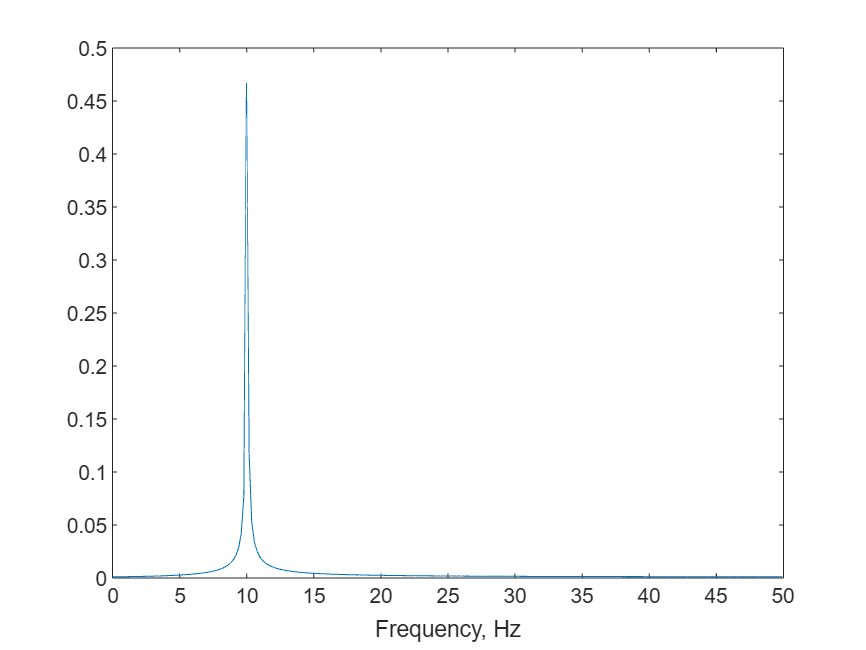

df = 1/T;
Fmax = 1/(2*dt);
K = 256;
f = [0:df:Fmax];
plot(f,abs(FY(1:K)/N)); xlabel ('Frequency, Hz')

## Application to Modulation Transfer Function (MTF) Measurement

Suppose we want to measure the MTF of an imaging system. We take the intensity profile of an edge image (one row, for example). We then take its derivative to create a 1-D line spread function. We take the FT of the line spread function and its modulus is the MTF. 

Let us first create an artificial edge. (Note : real edge images are noisy in the black and white parts. The example here is idealized).

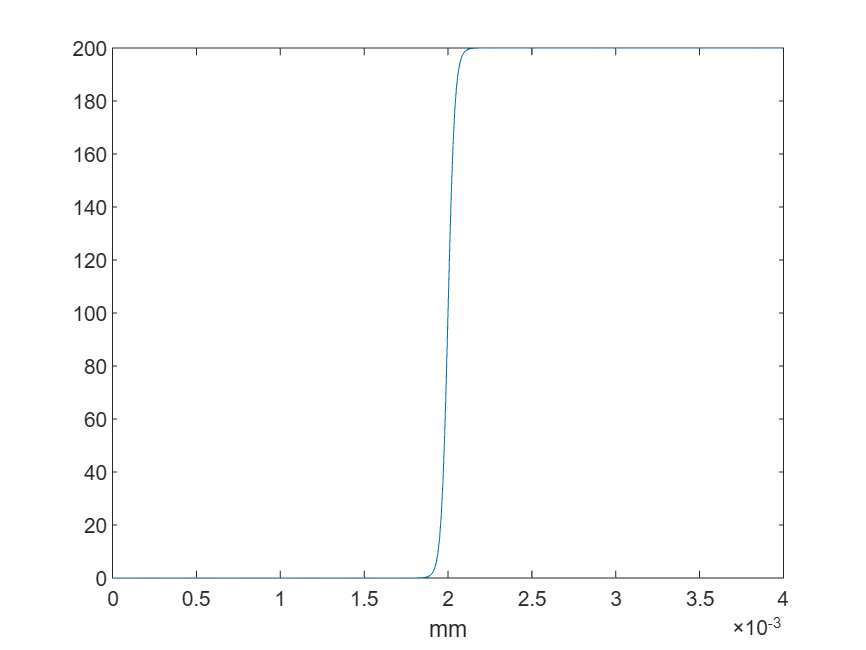

dx = 0.010e-3; %this is the size of the pixel in millimeters
N = 400; %this is the number of pixels in the edge profile.
%Here we use a sigmoid function to make an artificial edge intensity
%profile
x=[0:dx:(N-1)*dx];
B=50000; %this is just the steepness factor;
E = 200*1./(1+exp(-B*(x-200*dx)));
plot(x,E); xlabel('mm');

Now we take the derivative of the edge profile to get a line spread function.

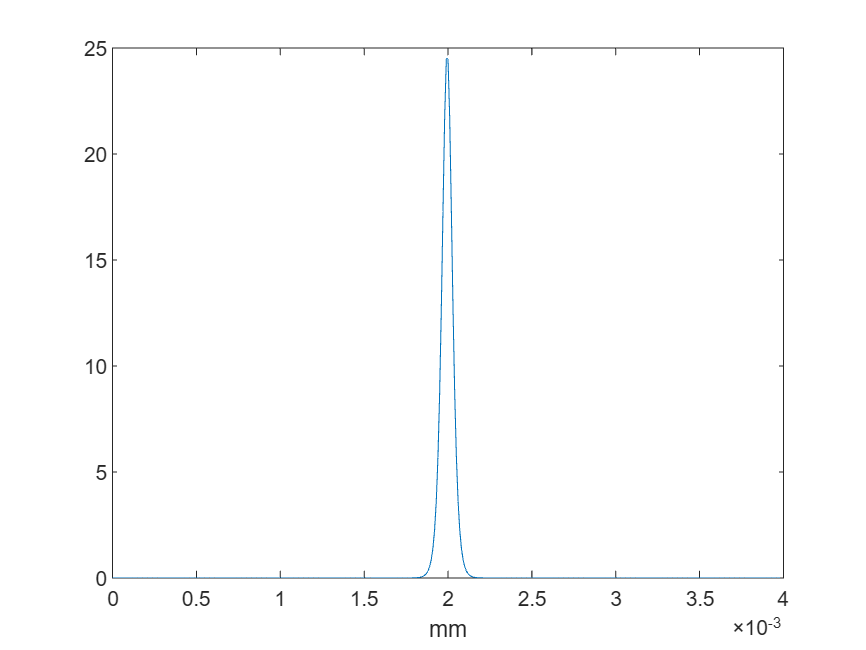

dE_dx = diff(E);
plot(x(1:N-1),dE_dx); xlabel ("mm"); %taking the derivative using diff results in an N-1 size output

Now we take the FFT of the line spread function and get its modulus.

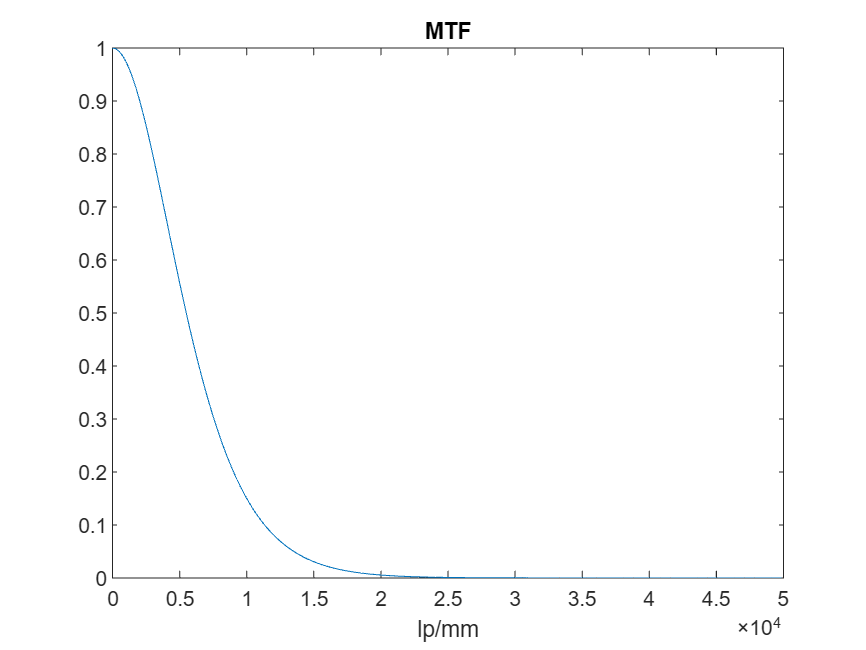

FdE_dx = fft(dE_dx);
MTF = abs(FdE_dx)/max(abs(FdE_dx));
Fmax = 1/(2*dx);
df = 1/((N-1)*dx);
K = 200; %Half of N;
f = [0:df:Fmax];
plot(f,MTF(1:K)); xlabel ("lp/mm"); title("MTF");

Take note that this output came from a noise-free, idealized edge. Real edge images will be noisy in the both black and white areas. Several MTFs must be taken from the same image and averaged to give a smoother MTF result.